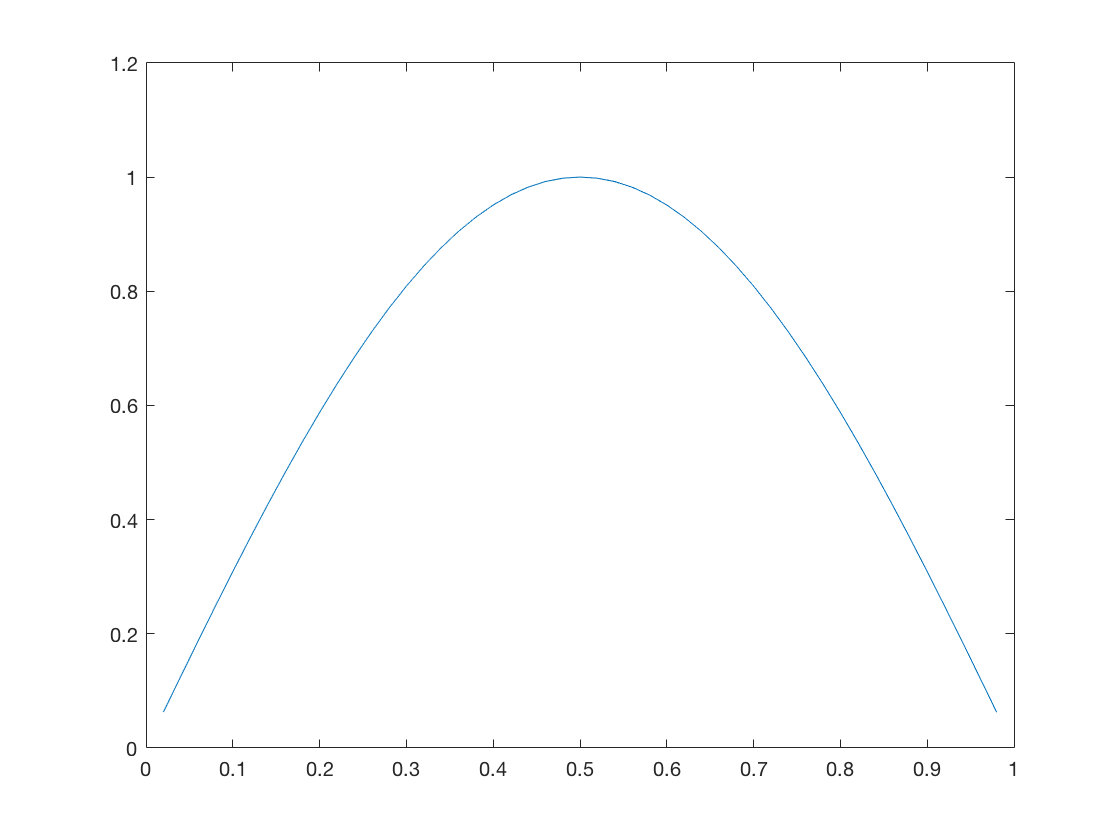

% Math 104B HW #4, March 15, 2018


% For #1 look at the TriDiag function below

% 2.

% Notice that we can make a matrix, call it A,
% with the diagonal being the coefficients of v_j
% the lower diagonal the coefficients of v_(j-1) and
% the upper diagonal the coefficients of v_(j+1), 
% i.e. a tridiagonal matrix

% a)
N=50;
h=1/N;
% Defining the Tridiag matrix
A=(2/(h^2)+pi^2)*eye(N-1,N-1);
for j=2:N-1
    A(j,j-1)=-1/(h^2);
    A(j-1,j)=-1/(h^2);
end
% Defining the b in Ax=b
for j=1:N-1
    b(j)=2*(pi^2)*sin(pi*(j*h));
    x(j)=(j*h); % for the plot
end

y=TriDiag(A,b);
plot(x,y);


% b)



$$\text{Notice that for } u(x)=\sin(\pi x) \text{,  } u(0)=\sin(0)=0=\sin(\pi)=u(1). \\
\text{Then, } u'=\pi\cos(\pi x)  \text{ and } u''=-\pi^2sin(\pi x). \\
\Rightarrow -u''+\pi^2u=\pi^2sin(\pi x)+\pi^2sin(\pi x)=2\pi^2sin(\pi x)$$



% c)

% By doubling the interpolation points, we
% expect the error to decrease by a factor of 4

% we do the same as N=50 in part a but for N=100
N1=100;
h1=1/N1;
% Defining the Tridiag matrix
A1=(2/(h1^2)+pi^2)*eye(N1-1,N1-1);
for j=2:N1-1
    A1(j,j-1)=-1/(h1^2);
    A1(j-1,j)=-1/(h1^2);
end
% Defining the b in Ax=b
for j=1:N1-1
    b1(j)=2*(pi^2)*sin(pi*(j*h1));
    x1(j)=(j*h1); % for the plot
end

y1=TriDiag(A1,b1);

% Now we get the true answer using u(x)=sin(x*\pi)
% Since we know sin(0)=sin(\pi)=0, we can exlude x_0=0 and x_n=0
for j=1:N-1
    T(j)=sin(pi*h*j); % true answer vector
end

for j=1:N1-1
    T1(j)=sin(pi*h1*j); % true answer vector
end

% we take the infinite norm
error=max(y-T');
error1=max(y1-T1');

% This gives us the factor of four we expected
error/error1

ans = 4.0001


% d)

% We find the approximation using N interpolary nodes and then
% using 2N interpolary nodes. Then divide them and get the ratio.
% Afterwards, do the same for 2N and 4N, 4N and 8N, 8N and 16N, etc...
% Notice how all these ratios converge to a certain number, which
% is the rate of convergence. This implies the general convergence 
% to the solution based on the proofs in class.


% 3.

% a)

% y2 is the approximated solution for N=50 using Jacobi
% iterations50 is the number of interations for this algorithm 
[y2,iterations50]=Jacobi(A,b);

iterations50

iterations50 = 1629


% y3 is the approximated solution for N=100 using Jacobi
% iterations100 is the number of interations for this algorithm 
[y3,iterations100]=Jacobi(A1,b1);

iterations100

iterations100 = 6515


% Notice how it takes much longer to compute
% twice the amount of interpolary points.

% b)

% y4 is the approximated solution for N=50 using Gauss Seidel
% iterations50 is the number of interations for this algorithm
[y4,iterations50]=Gauss_Seidel(A,b);
iterations50

iterations50 = 915



% y5 is the approximated solution for N=100 using Gauss Seidel
% iterations100 is the number of interations for this algorithms 
[y5,iterations100]=Gauss_Seidel(A1,b1);
iterations100

iterations100 = 3634


% Notice how it takes much longer to compute
% twice the amount of interpolary points.


function x = TriDiag(A,d)

% Getting the size of all the matrices and initializing vars, matrices
[~,n]=size(A);
m=[];
c=[];
m(1)=A(1,1);
U=zeros(n);
L=zeros(n);

% Coefficients in the factorization
for j=1:n-1
    % initialize the b's and c's of the A matrix
    % for clarity's sake
    b(j)=A(j,j+1);
    c(j)=A(j+1,j);
    l(j)=c(j)/m(j);
    m(j+1)=A(j+1,j+1)-l(j)*b(j);
    
    % Define Upper and Lower Matrices
    U(j,j+1)=b(j);
    U(j,j)=m(j);
    L(j+1,j)=l(j);
    L(j,j)=1;
end
U(n,n)=m(n);
L(n,n)=1;

% Forward sub on Ly=d (from previous HW)
y=forwardsub(L,d);

% Backward sub on Ux=y (from previous HW)
x=backwardsub(U,y);


end



function x = forwardsub(A,b)
    [n,~]=size(A);
    x=zeros(n,1);
    x(1)=b(1);
    for j=2:n
        x(j)=(b(j)-A(j,:)*x)/A(j,j);
    end
end



function x = backwardsub(U,b)
    [n,~]=size(U);
    x=zeros(n,1);
    x(n)=b(n)/U(n,n);
    for j=n-1:-1:1
        x(j)=(-U(j,:)*x+b(j))/U(j,j);
    end
end



function [x,iteration] = Jacobi(A,b)

% Defining the W Matrix
[n,~]=size(A);
for j=1:n
    W(j,j)=A(j,j);
end

N=n+1;
h=1/N;
x{1}=zeros(n,1);
j=1;
iteration=0;

while ~(max(b-A*x{j})<(.1*h))
    x{j+1}=(eye(n)-(eye(n)/W)*A)*x{j}+(eye(n)/W)*b';
    j=j+1;
    iteration=iteration+1;
end

x=x{j};

end



function [x,iteration] = Gauss_Seidel(A,b)

[n,~]=size(A);

% defining W
W=tril(A);
for j=1:n
    W(j,j)=A(j,j);
end

N=n+1;
h=1/N;
x{1}=zeros(n,1);
j=1;
iteration=0;

while ~(max(b-A*x{j})<(.1*h))
    x{j+1}=(eye(n)-(eye(n)/W)*A)*x{j}+(eye(n)/W)*b';
    j=j+1;
    iteration=iteration+1;
end

x=x{j};


end


